# **Worksheet 8: Newton's Method (and Secant Method)**

**Directions: ****Change your working directory to your Flash drive and save this file on it.** Read through this document and run any Example code. Then try the Problems yourself. The solutions will be posted on Canvas later. When you've completed the Worksheet, you can start the Lab.

Last worksheet, we looked at an example of a root-finding algorithm (solving $f(x)=0$), the Bisection Method. Today we return to a classic root-finding technique you may have learned in Calculus I – Netwon’s Method.

If you learned Newton’s Method in Calculus, you probably learned it from a graphical approach. Recall that the method takes an initial guess $x_0$ of the root, computes a tangent line to the function $f$ at that point, and then finds where the line intersects the $x$-axis. That point becomes our next guess $x_1$ at the root, and the process is repeated until a desired tolerance is achieved (or the method diverges away from our root!).

Example #1:  This graph illustrates Newton’s Method in progress:

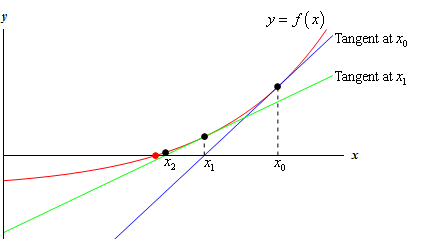

We can also derive Newton’s Method by using Taylor Polynomials: Suppose that $f$ is a continuously differentiable function on the interval $[a,b]$ and let $r \in (a,b)$ be a root of $f$ (so $f(r) = 0$).  Let $x_0 \in [a,b]$ be an approximation to $r$ (where $f'(r) \neq 0$) and the difference between $r$ and $x_0$ is "small." Then the Taylor expansion of $f(r)$ around $x_0$ is:

$f(r) = f(x_0) + (r-x_0)f'(x_0) + O((r - x_0)^2))$.

Since $r$ is a root of $f$,


$$0 = f(x_0) + (r-x_0)f'(x_0) + O((r - x_0)^2))$$
 

Since $(r - x_0)$ is small, $(r - x_0)^2$ is really small, so,

$0 \approx f(x_0) + (r - x_0) f'(x_0)$.

Then we just solve for $r$ and call it our new iterate $x_1$,

$r \approx x_0 - \frac{f(x_0)}{f'(x_0)} \equiv x_1$.

Thus, Newton’s Method is born!  We traditionally write it as:


$$x_{i+1} = x_i - \frac{f(x_i)}{f'(x_i)}$$


Download the newton.m file from Canvas. Make sure it is in the same directory (i.e. current folder) as this worksheet file so you can run this function. Once you’ve put them in the appropriate folder, open the files in MATLAB and **read the code** and gain an understanding of what's happening. Pay special attention to what's happening within the while loop.

This function takes an initial value $x_0$ an optional argument of an accuracy tolerance tol, and an optional argument of a maximum number of function iterations $n$  and performs Newton's Method on the function given in the subfunction $f$ in the code. If you want to change the function whose root you're finding, you must edit this subfunction$f$ to be your desired function **and its derivative!**

**PROBLEM #1:**  Find the roots of $f(x) = x^2 - x - 2$ by hand. Then find a root of $f$ by using the `newton `algorithm with an $x_0 = 1.5$ using the default tolerance and maximum iteration values in the code box:

**Since the function factors to **$f(x) = (x - 2)(x + 1)$** roots are 2 and -1...**

% Put your code here.

T = newton(1.5)

T = 5×2 table
    i          x_i       
    _    ________________

    0                 1.5
    1               2.125
    2    2.00480769230769
    3    2.00000768001966
    4    2.00000000001966


How many iterations did it take before the algorithm stopped? What is Newton's estimate of the root? Compute your unsigned absolute and relative error. How do these relate to the tolerance we set (i.e. is the tolerance the absolute or relative error or something completely different)?  What exactly is the stopping criterion for the algorithm?

 **Only 4 iterations.**

x = T{:,'x_i'};
abs_error = abs(x(end) - 2)

abs_error =        1.9660717498482e-11


rel_error = abs_error/2

rel_error =       9.83035874924099e-12


**Neither of these values are related to the tolerance. The tolerance is a relative check between successive guesses, not to the true value, since the true value is (usually) unknown. The stopping criteria are when the relative error between successive iterates gets small enough (based on the passed in or default tol value) or when the number of iterations hits the maximum allowable (based on the passed in or default n value).**

**PROBLEM #2:  **Now repeat the process from Problem #1 using Fixed-Point Iteration to find the **root** (not fixed point!) of $f$ using your fpi.m file. Use the same initial condition as Problem #1. Report the number of iterations before the algorithm ended, the estimate of the root, and theunsigned absolute and relative error. Which method (Newton vs Fixed-Point) is faster? Which method is more accurate (given the same tolerance)?

**The iteration function I'll use is **$g(x) = x^2 - 2$ **which has fixed points at the same roots of **$f(x)$

% Put your code here.

T = fpi(1.5)

T = 110×2 table
    i            x_i        
    __    __________________

     0                   1.5
     1                  0.25
     2               -1.9375
     3            1.75390625
     4      1.07618713378906
     5    -0.841821253066882
     6      -1.2913369778849
     7    -0.332448809547084
     8     -1.88947778903073
     9      1.57012631524044
    10     0.465296645810533
    11     -1.78349903139747
    12       1.1808687949957
    13    -0.605548889005393
    14     -1.63331054302433
    15     0.667703329954447


x = T{:,'x_i'};
abs_error = abs(x(end) - 2)

abs_error =       0.000428866054171806


rel_error = abs_error/2

rel_error =       0.000214433027085903


 **It looks like FPI with that iteration function is much worse than Newton's Method in terms of speed and accuracy.**

You’ve seen by now that Newton’s Method is an extremely strong technique.  It does, however, have a few weaknesses.  We will explore one of them now.

**PROBLEM #3: ** Just like in Problem #1, you will find the root of $f(x) = x^2 - x - 2$ by using the `newton `algorithm. This time use $x_0 = 0.5$ in the code block below:

% Put your code here.

newton(0.5)

ans = 3×2 table
    i    x_i
    _    ___

    0    0.5
    1    Inf
    2    NaN


Did the algorithm converge to the root?  Why not?  (HINT:  Try iterating Newton’s Method by hand a few times.)

**No, Newton's Method didn't converge because **$f'(x) = 0$** at that value, so you're dividing by zero and the method fails.**

So Newton’s Method can break down when due to something about using the derivative of $f(x)$. We can avoid this problem by using a method based on Newton’s, called the Secant Method.

The Secant Method is the same as Newton’s, except we use the idea that:

$f'(x_i) = \lim_{x \rightarrow x_i} \frac{f(x) - f(x_i)}{x - x_i}$, and if $x_{i-1}$ is close to $x_i$ then $f'(x_i) \approx \frac{f(x_{i-1}) - f(x_i)}{x_{i-1} - x_i} = \frac{f(x_{i}) - f(x_{i-1})}{x_i - x_{i-1}}$

which we substitute in to Newton’s Method:


$$x_{i+1} = x_i - \frac{f(x_i)}{f'(x_i)}$$


to receive the Secant Method:

$x_{i+1} = x_i - \frac{f(x_i)(x_{i} - x_{i-1})}{f(x_{i}) - f(x_{i-1})}$. This avoids invoking the derivative.

I’ve written a function `secant``.m` which you can find on Canvas. You must input *two *initial guesses, $x_0$ and $x_1$ (and can optionally also give a tolerance and max number of iterations) similar to Bisection Method.

Ponder this:  Why do you think the method is named the *Secant* Method?

**Because it's forming a secant line between the two points.**

**PROBLEM #4: ** Just like in Problem #3, you will find the root of $f(x) = x^2 - x - 2$ with $x_0 = 0.5$ and $x_1 = 1.5$, but now you will use `secant.m` in the code block:

% Put your code here.

secant(0.5,1.5)

ans = 6×2 table
    i          x_i       
    _    ________________

    0                 1.5
    1                2.75
    2    1.88461538461538
    3    1.97619047619048
    4    2.00096030729834
    5    1.99999232001966


Did the algorithm converge to the root?

**Yes.**

How did the Secant Method perform compared to Newton’s with $x_0 = 0.5$ and to Newton's with $x_0 = 1.5$ (see Problems #1 and 3 for the Newton results)?

**Newton with **$x_0 = 0.5$** didn't work at all because **$f'(0.5) = 0$**, however, Newton with **$x_0 = 1.5$** did work and was faster (sort of, it was 1 iteration faster, but Secant requires 1 additional guess) than Secant Method. It's more evident that Newton is faster because it was much closer to the true value than Secant after the same(ish) number of iterations. Secant Method is slower, but it won't mess up when the derivative is 0.**